# Sygnały rzeczywiste

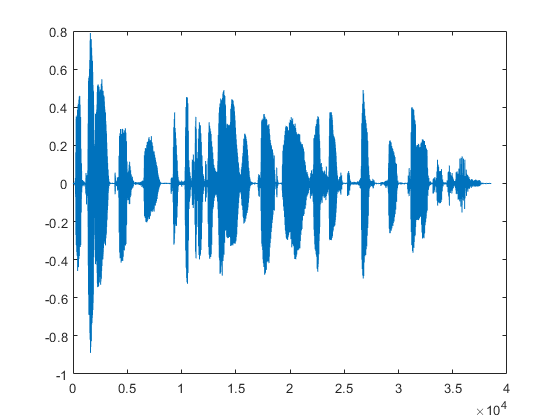

[x, fs] = audioread('mowa.wav');

figure
plot(1:length(x),x)



N = 256;
% z zadania 01
wk = @(k,n) sk(k,N)*cos(pi*(k/N)*(n+0.5));

% generate matrix A
A = zeros(N,N);
for k=0:N-1
    for n=0:N-1
        A(k+1,n+1) = wk(k,n);
    end
end

% wybieram punkty
pts = [17500, 26700, 4200,1150,14700,29000, 31000, 10300, 16300,23500];
MN = zeros(10, 256);
y = zeros(10,256);

for i=1:10
    NM(i,:) = x(pts(i):pts(i)+255);
    y(i,:) = A*NM(i,:)';
end

prezentacja danych

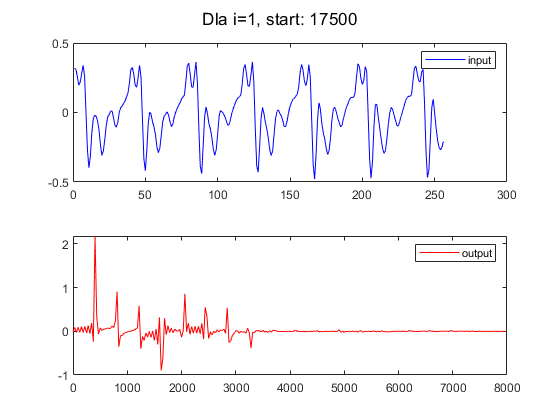

figure
for i=1:10
    clf
    
    subplot(2,1,1);
    plot(NM(i,:), 'b')
    legend({'input'});
    
    hold on
    subplot(2,1,2); 
    plot((0:length(y(i,:))-1)*fs/length(y(i,:)), y(i,:), 'r')
    legend({'output'});
    sgtitle(['Dla i=',num2str(i),', start: ', num2str(pts(i))])
    
    pause(0.1)
end

funckje:

function s = sk(k,N)
    if k==0
        s = sqrt(1/N);
        return
    end
    s = sqrt(2/N);
end